# **Final Project**

Group Members: Madeline Laesser, Jade Lecker, Hudson McGaughey

### Introduction

    The main theme of our project is looking at fluvial dunes. Fluvial dunes are dunes that occur when a fluid interacts with an erodible bed beneath it. In our case, we will be looking at dunes on the bed of rivers with sand on the floor. Specifically, we will look at a canonical evolution equation that can solve for the height of the dune over the movement across the horizontal axis of the river bed. We are using an equation from a paper called the Mathematical Modeling of Dune Formation by David Cocks. 

    The study of fluvial dunes can be important for the health of the river’s ecosystem and predicting/preventing floods. According to a paper in the Journal of Geophysical Research called *The Fluid Dynamics of River Dunes: A Review and Some Future Research Directions*, fluvial dunes are “vital in predicting flow resistance, sediment transport, and deposition within many rivers.” Some examples of how knowing this is important are as follows. A higher flow resistance corresponds to slower flow right which can cause higher water levels and subsequently, flooding. Sediment deposition can modify the river bed which can affect the river’s ability to carry flood waters. Different river species need different river flow conditions. Predicting these flow conditions can help us manage habitats. Overall, the study of fluvial dunes can give us insight into the protection of the environment.

    Since this class is at the undergraduate level, the model and equation we are using are more simplified than might be used in other studies. The paper by David Cocks that we found our equation in actually takes the equation a few steps further. Our equation is a fairly simple PDE, but the paper takes the Fourier transform and uses the Fourier spectral method. In our project, we attempt to solve it multiple ways, but all of them are different from the Fourier spectral method. Also, there are different models and equations based on assumptions. We made the assumption that we have a saturated bedload transport, but in other people’s work they use models that have a non-saturated bedload transport. Another method for studying fluvial dunes is by using data collected from tools like flume experiments and vibrocorers. An example of this is found in an article by Kleinhans over fluvial dunes in a river in the Netherlands. Methods that rely on collecting data can be difficult because of the challenges that come with measuring sediment in river beds. Lastly, the boundary conditions we chose to use may be different in other people's work as we had trouble finding information on the boundary conditions, so we chose some that made the most sense to us. 

### Equations

**Canonical Evolution Equation**

**2.196       **                     $\frac{\partial S}{\partial T}+S\frac{\partial S}{\partial X}=\frac{\partial^2 S}{\partial X^2 }-\int_0^{\infty } \frac{\partial^2 S}{\partial X^2 }\left(X-\xi ,t\right)\xi^{-\frac{1}{3}} d\xi$

**Simplified Canonical Evolution Equation**

**2.197  **                                ${\mathit{\mathbf{s}}}_{\mathit{\mathbf{t}}} +{\textrm{ss}}_{\mathit{\mathbf{x}}} +\mathit{\mathbf{K}}*{\mathit{\mathbf{s}}}_{\textrm{xx}} -{\mathit{\mathbf{s}}}_{\textrm{xx}} =0$

**Burger's Equation**


$$\frac{\partial u}{\partial t}+u\frac{\partial u}{\partial x}+u\frac{\partial u}{\partial y}=v\frac{\partial^2 u}{\partial u^2 }+v$$

$$\frac{\partial^2 u}{\partial y^2 }$$


    The formation of dunes is found when a force interacts with an erodable bed, whether that's wind blowing sand or water moving particles from the riverbed. Because of the unpredictability of fluids and the movement of particles, this model is fairly complex to model and simulate. However, the equations as listed from the model describe a type of dune called a fluvial dune, which accounts for the formation of dunes in a river.  

    Modeling dunes in a riverbed is easier than the desert, as the water is confined to a channel, making the flow of water simpler than the wind. Because of this, there is usually less variety in the form. The physical processes in the creation and deposition of fluvial dunes depends on the the flow rate of the water above it, as well as the composition of the riverbed and the sediment. The force of the river moves the particles, causing them to either be deposited downstream or move along the surface of the bed. "Dunes more slowly in the direction of low, and have a shallow upstream slope with a steep downstream slope" (Cocks 2005). Dunes form as the water flow in a river begins to increase, beginning with small ripples in the surface of the bed. 

    The form of the canonical evolution equation in 2.197 is derived by a Fourier spectral method; however, its initial form in 2.196 is related to Burger's equation, which is a fundemental partial differential equation that evaluates convection-diffusion. In this context, a canonical evolution, or canonical transformation, refers to an equation that describes how a vector changes over time, a useful tool when evaluating adaptive dynamics. Below is a simplified animation showing how dunes move in the direction of the flow of water.

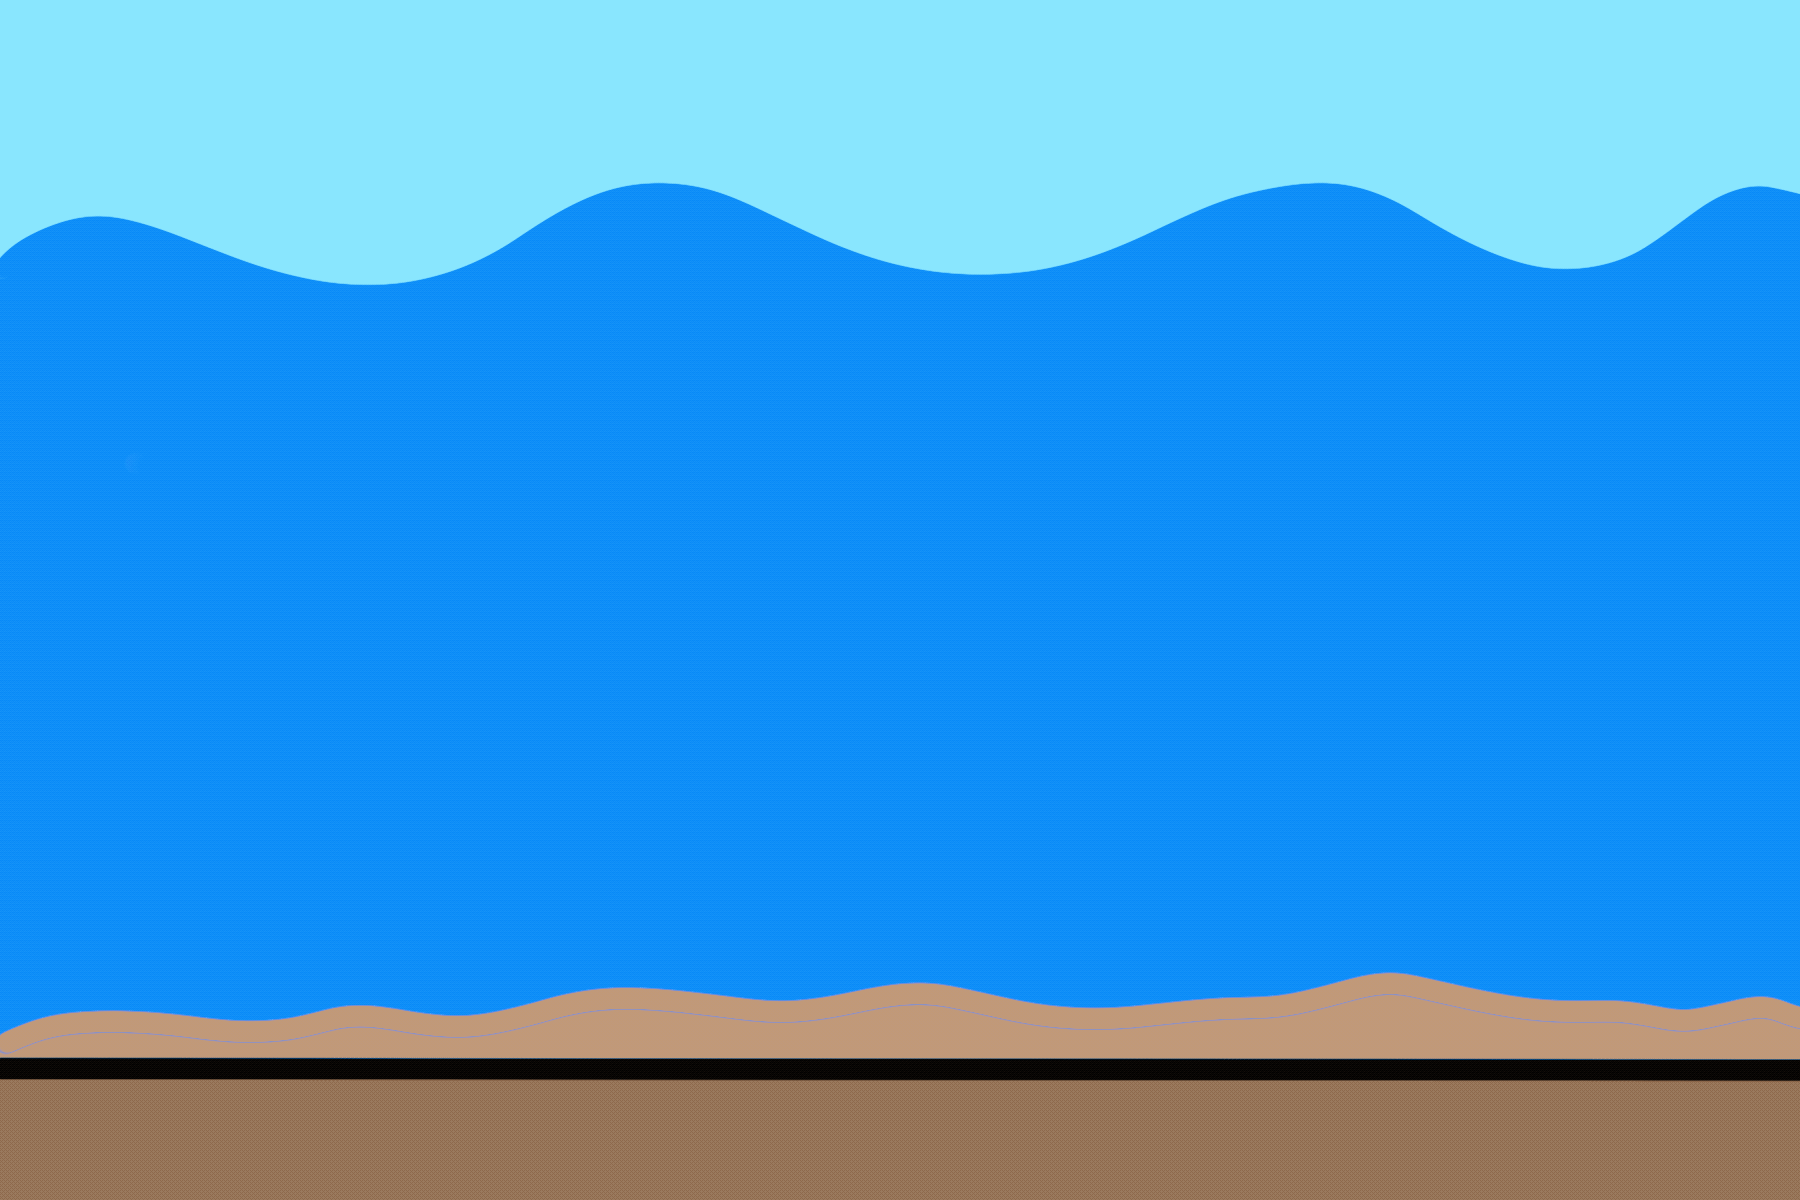

*Animation 1: dunes forming with the flow of water*

**Parameters**


$$\begin{array}{l}
\;s=s_0 e^{\sigma t+i\left(\mathrm{kx}+\mathrm{ly}\right)} \\
K\left(x\right)=x^{-\frac{1}{3}} \\
C=\frac{\mathrm{dx}}{\mathrm{dt}\;}=100\\
D=\frac{\mathrm{dx}}{{\mathrm{dt}}^2 }=10,000
\end{array}$$


    Beginning with the steps of the method, the time step is 0.1 units and the horizontal length step is measured by 1 meter movements. The Courant number is essential for advection-diffusion partial differential equations, which is how the fluvial dune model is constructed. The Courant number is a representation for “the number of mesh cells traveled within a given distance” (SimScale), where a mesh cell is a small discrete representation of a larger model. The diffusive term, D, represents the action of a small-scale process to mix a quantity from a high concentration to a low concentration. These parameters do not appear in the provided equations; however, they are essential for evaluating an advection-diffusion equation, such as the dune model.

    In the initial canonical evolution equation 2.196, S refers to the mean slope of the bed, X is horizontal length, T is the unspecified unit of time, and $\xi$ is an integration constant. 

    In the simplified canonical evolution equation of 2.197, the terms as described are s, the bed slope elevation, $s_t$, the time derivative of the bed slope elevation, $s_x$, the time derivative of the bed slope elevation, $s_{\textrm{xx}}$, the second time derivative of the bed slope elevation, and finally, K, which is the convolution kernel. A convolution expresses the amount of overlap between functions, or in other words, "blending" of two functions. In 2.197, it is the inverse of the cube root of horizontal length.

**Initial conditions**


$$\begin{array}{l}
x_0 =0\\
t_0 =0\\
s_0 =5
\end{array}$$


**Boundary conditions**

    For our simulation, we chose different boundary conditions to simulate. To begin, we chose a no flux boundary condition, meaning that the advection and diffusion terms are in balance, resulting in no net change in the mass balance of the model. 

    Then, we implemented a periodic boundary system, meaning that any particles that leave the system will re-enter the system. A periodic boundary is essential for evaluating an infinite model by creating a box that can be replicated repeatedly throughout an infinite time period. The result of this model represents an infinite amount of dunes with arbitrary wavelength (Cocks), so constructing the model within these boundary conditions allows a simplification in which we can approximate the result of the analysis of this complex model.

**Assumptions**

    Assumptions made in this model begin with simplfying the dune model, as this is a fairly complex model due to the unpredicatability of the interaction between the movement of fluid and the erodable bed. By changing the values of some of the variables to a constant, the equation becomes easier to evaluate. In this case, by assuming the initial bed elevation to be greater than 1 over a length of greater than 1,  many of the variables are eliminated, resulting in 2.196, the canonical evolution equation. To further simply this equation, 2.196 is given a solution by a Fourier spectral method, as the integral is a convolution. 

    For our evaluation of the model, we will be looking at 2.197 over a horizontal length of 1000 meters with a step of 1 meter and a time length of 0.1 units because this model is defined to represent an infinite amount of dunes over an arbitrary amount of time. Because we wanted to evaluate this model based on levels of complexity, we also assumed that the convolution featured in 2.197 as simple multiplication, and with each simulation, we altered that term by including the Fourier convolution, as seen in 2.196. 

### Numerical Methods

**Advection-Diffusion Equation**

    To numerically solve the rewritten canonical evolution equation 2.197 from the text, we used the numerical method of the advection-diffusion equation, as the left side of 2.196, initial canonical evolution equatio, the equation contains convecting waves on the left-hand side that form shocks and a diffusive term on the right-hand side, "stabilizing short-wavelength distrubances and smoothing out shocks" (Cocks). The dunes model describes the formation of dunes through turbulent geophysical flow, which describes the physical interpretation of how the particles are moved within a system due to advection and diffusion.

**CODE**

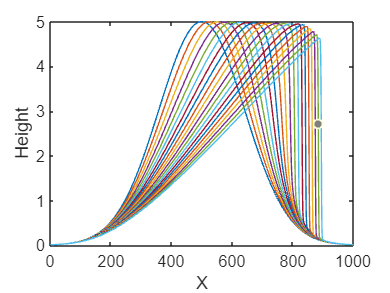

% horizontal length
x0 = 0;
xf = 1000;
% time
t0 = 0;
tf = 100;
% time steps
dx = 1;
dt = .01;
% initial conditions
C = dt/dx;
D = dt/dx.^2;
nx = (xf-x0)/dx;
nt = (tf-t0)/dt;
x = linspace(x0,xf,nx);
t = linspace(t0,tf,nt);
K = x.^(-1/3);
s = zeros(nx,nt);
s(:,1) = 5*exp(-(.005*x-2.5).^2);

for k = 1:nt-1
    for i = 2:nx-1
        s(i,k+1) = -C*(s(i,k)).^2 + s(i,k) * (1 + C*s(i-1,k)+2*D*(K(i)-1)) - D*(K(i)-1)*(s(i-1,k)+s(i+1,k));
    end
    s(1,k+1) = s(2,k+1);
    s(end,k+1) = s(end-1,k+1);
end

% plotting
plot(x,s(:,1:500:end));
xlabel('X');
ylabel('Height');

### Results

    We ran 3 different simulations. Our first was a model of Burger’s equation, which is similar to the advection equation, but with a diffusion term. This equation is similar to that found by the authors in the paper, but it excludes the convolution term entirely, only having advection and diffusion. This is a simple model of fluid flow, which is a good approximation for the flow of a sand dune. Our second simulation was an expanded version of this that sought to get a little closer to the original equation given by the authors by including the term which has the convolution of the function x-1/3 with the second derivative of s subtracted from our original equation. This was first done by the simplification of treating the convolution like simple multiplication. Finally, we attempted to get closer to the author’s true model by including an integration step within our loop calculating s at each point in space-time. This integral was added on to each point in space at each time step to account for the term. Our method for this last simulation unfortunately did not work, likely due to our very different approach from the authors. We set the initial condition as a Gaussian curve and set the boundary conditions to have no flux at both ends to simulate a flattening of the dune at the ends. 

    In our first two models, we got very similar results. Both showed curves of the same shape developing, with a smooth curve up to a point, but eventually becoming a sharp corner regardless of the parameter values. This is likely a result of instability slowly developing, and seems to happen even for Courant number values significantly smaller than 1, only happening more slowly with a smaller Courant number. While this is not a perfectly accurate reflection of the results of the author, the average height does diminish over time and the slope becomes increasingly flatter on top, similar to their results with a largely flat peak. There were not appreciable differences in the results of the model with and without the function multiplying the diffusion term, with both having the same overall shape and showing the same increasing instability. However, we struggled to get useful results when trying to fully emulate their model with the convolution. Our model showed a rapidly increasing total amount of sand, which is the opposite expected of such a model, and the total amount of sand quickly blew up. This model was obviously not accurate, but we were struggling to make the convolution integral term work using our methods

    The results are not particularly close to those found in the model we based it on. The primary reason for this is the convolution integral; because the convolution involves the second derivative of s, which is the function we are trying to solve for, there is not a clean way to handle it with numerical methods. For our method, we tried to just do the integration at each time step and add in a term for it once at every time step, but I believe this did not handle it properly. This term has major effects on the outcome, and its treatment heavily changes the characteristics of the results. The author handled this problem by applying higher level math, using the Fourier Transform to turn the PDE into an ODE, which was then solved with the Forward Euler method. These concepts are beyond the scope of this class though, so we simply tried to compute it directly. There was likely something we overlooked in our computation, or it was simply not the correct way to handle such a term, but we attempted to use trapezoidal integration. This yielded instability, with figures not generating curves beyond the first time step.

*How do the results change with different methods, time steps, grid spacing, or model parameters?*

*    ******

    This model explains that the formation of dunes is highly complex. Regardless of the simplifications of the model from the thesis, we still had a hard time solving this model, as we didn't really know how to accurately handle the convolution. In the context of natural processes, there can be models that predict events, outcomes, or in this case, the formation of dunes, but there will always be a notion of unpredictability, such as the bethymertry, waterflow, bed composition, and so many more aspects of the natural process that had to be assumed or simplified for this model to work. 

    The model could be improved by providing a more in-depth explanation of the canonical evolution equation, as we found it difficult to decipher the convolution in 2.197 and the integration in 2.196. The thesis paper did not explain much regarding the derivation of 2.196, nor did it explain the entire process in simplifying it into 2.197. Many of the terms were undefined, and there were variables that were never explained. By thoroughly explaining the derivation process and the convolution kernel K(x), this model would have been easier to analyze, as well providing boundaries and initial conditions. During our evaluation of this process, we concluded to experiment with different boundary conditions, as well as initial conditions. For a further explanation, the numerical analysis of this model was outside our knowledge and the scope of this course, so we had to evaluate this model in a different aspect, such as treating the convolution differently in each simulation. While we didn't know how to solve this model exactly as the author did, we still were able to provide figures that resembled the solution from David Cock's thesis.

### Figures

**REFERENCES**

Cocks, D. (2005). Mathematical modelling of dune formation.

“What Is a Mesh?: SimWiki Documentation.” *SimScale*, 17 Feb. 2023,    

         www.simscale.com/docs/simwiki/preprocessing/what-is-a-mesh/. 

### Video Walkthrough

*TBD*

*RANDOM EDIT HERE*